% 间歇性专用车道情况对比
clear; clc; close all;
%
%-----------------------------
% 1. 关于theta
%——---------------------------
D = 4000; % 需求规模
s = 2000;

alpha1 = 6.4;         
beta = 0.61*alpha1;
gamma = 2.38*alpha1;

n = 6;
Cb = 20;
Cab = Cb/n; % 平均公交成本
Ct = beta*gamma/(beta+gamma)*D/s;        % 全私家车通勤成本

lambda = 4;        % 模块化公交效率参数
R_Nm_star = 500;      % 固定收益（R(N_m^*)）


%-------------------------------
% 专用道系数
%-------------------------------
theta = linspace(0.01, 0.99, 500);  % 必须小于 alpha1


Nm = theta .* lambda ./ (1 - theta + theta .* lambda) * D / (2 * n) ...
     .* (1 -  (Cab / Ct))

Nm =     6.0022    7.1401    8.2652    9.3776   10.4776   11.5653   12.6410   13.7049   14.7572   15.7979   16.8275   17.8459   18.8535   19.8503   20.8365   21.8124   22.7780   23.7336   24.6793   25.6152   26.5415   27.4583   28.3658   29.2641   30.1534   31.0338   31.9055   32.7685   33.6230   34.4691   35.3069   36.1366   36.9583   37.7720   38.5780   39.3763   40.1670   40.9503   41.7262   42.4948   43.2563   44.0107   44.7581   45.4987   46.2326   46.9597   47.6803   48.3944   49.1020   49.8034



p = 0.5 * (Ct + Cab)

p = 4.7742


Pi = n .* Nm .* p + R_Nm_star - Nm .* Cab

Pi = 1.0e+03 *

    0.6519    0.6807    0.7092    0.7374    0.7652    0.7927    0.8200    0.8469    0.8735    0.8999    0.9259    0.9517    0.9772    1.0024    1.0274    1.0521    1.0766    1.1007    1.1247    1.1484    1.1718    1.1950    1.2180    1.2407    1.2632    1.2855    1.3076    1.3294    1.3511    1.3725    1.3937    1.4147    1.4355    1.4561    1.4765    1.4967    1.5167    1.5365    1.5562    1.5756    1.5949    1.6140    1.6329    1.6517    1.6702    1.6886    1.7069    1.7250    1.7429    1.7606


CS = 0.5 * (lambda-1) ./lambda .* Ct .* n .* Nm

CS = 1.0e+03 *

    0.0839    0.0998    0.1156    0.1311    0.1465    0.1617    0.1768    0.1916    0.2064    0.2209    0.2353    0.2496    0.2636    0.2776    0.2914    0.3050    0.3185    0.3319    0.3451    0.3582    0.3712    0.3840    0.3967    0.4092    0.4217    0.4340    0.4462    0.4582    0.4702    0.4820    0.4937    0.5053    0.5168    0.5282    0.5395    0.5506    0.5617    0.5726    0.5835    0.5942    0.6049    0.6154    0.6259    0.6362    0.6465    0.6567    0.6668    0.6767    0.6866    0.6964


SW = CS + Pi

SW = 1.0e+03 *

    0.7359    0.7806    0.8248    0.8685    0.9117    0.9545    0.9967    1.0385    1.0799    1.1208    1.1612    1.2013    1.2409    1.2800    1.3188    1.3571    1.3951    1.4326    1.4698    1.5066    1.5430    1.5790    1.6147    1.6500    1.6849    1.7195    1.7537    1.7877    1.8212    1.8545    1.8874    1.9200    1.9523    1.9843    2.0160    2.0473    2.0784    2.1092    2.1397    2.1699    2.1998    2.2294    2.2588    2.2879    2.3167    2.3453    2.3736    2.4017    2.4295    2.4571


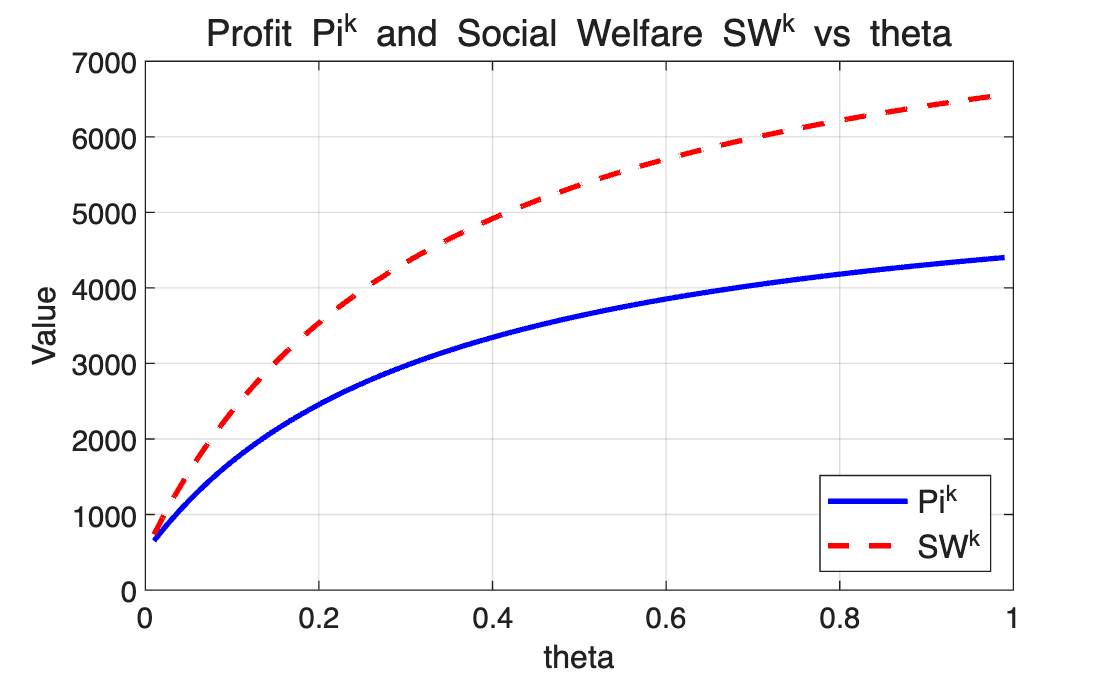


%-------------------------------
% 绘图
%-------------------------------
figure;
plot(theta, Pi, 'b-', 'LineWidth', 2); hold on;
plot(theta, SW, 'r--', 'LineWidth', 2);

xlabel('theta', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Profit Pi^k and Social Welfare SW^k vs theta', 'FontSize', 14);
legend({'Pi^k', 'SW^k'}, 'FontSize', 12, 'Location', 'best');

grid on; box on;


%






%{
clear; clc; close all;

%-----------------------------
% 2. 关于 lambda
%-----------------------------
D = 4000; % 需求规模
s = 2000;

alpha1 = 6.4;
beta = 0.61 * alpha1;
gamma = 2.38 * alpha1;

n = 6;
Cb = 20;
Cab = Cb / n; % 平均公交成本
Ct = beta * gamma / (beta + gamma) * D / s; % 全私家车通勤成本

theta = 0.3;
R_Nm_star = 500; % 固定收益

%-------------------------------
% 自动驾驶水平
%-------------------------------
lambda = linspace(1.0, 9.9, 500)

Nm = theta .* lambda ./ (1 - theta + theta .* lambda) * D / (2 * n) ...
     .* (1 -  (Cab / Ct))

p = 0.5 * (Ct + Cab)

Pi = n .* Nm .* p + R_Nm_star - Nm .* Cab
CS = 0.5 * (lambda-1) ./lambda .* Ct .* n .* Nm
SW = CS + Pi

%-------------------------------
% 绘图
%-------------------------------
figure;
plot(lambda, Pi, 'b-', 'LineWidth', 2); hold on;
plot(lambda, SW, 'r--', 'LineWidth', 2);

xlabel('$\lambda$', 'Interpreter','latex', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Profit $\Pi^k$ and Social Welfare $SW^k$ vs $\lambda$', ...
      'Interpreter','latex', 'FontSize', 14);
legend({'$\Pi^k$', '$SW^k$'}, 'Interpreter','latex', ...
       'FontSize', 12, 'Location', 'best');

grid on; box on;

%}
